Define system params

close all
clear all
clc
m= 1000; %kg, mass of the vehicle
I=1500; %kgm^2, moment of inertia of the vehicle
a=1.5; %m, distance from the center of mass to the front axle
b=1.5; %m, distance from the center of mass to the rear axle
c=1; % The distance from the center of mass to the left/right side of the tires (y axis)
parameters=[m;I;a;b;c];

V=20;
eps_0=[0;0;0;0.9*V];
lanewidth=3.5;
lanes=3;

MPC

%Sampling time of T_s=0.05
Ts=5e-2;
u_0=zeros(2,1);
[dsys,U,Y,X,DX]=(discreteSS(eps_0,u_0,parameters,Ts));
mpcobj=mpc(dsys);

-->The "PredictionHorizon" property is empty. Assuming default 10.
-->The "ControlHorizon" property is empty. Assuming default 2.
-->The "Weights.ManipulatedVariables" property is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property is empty. Assuming default 1.00000.
   for output(s) y1 y2 and zero weight for output(s) y3 y4 


STEPS:

- Define prediction horizon

mpcobj.PredictionHorizon = 60; %2 sec
mpcobj.ControlHorizon=2; %0.1 Sec

- Constraints on Control (Max Throttle, Max throttle rate of change. Max steering angle,)

mpcobj.ManipulatedVariables(2).RateMin = -0.2*Ts;
mpcobj.ManipulatedVariables(2).RateMax = 0.2*Ts;
mpcobj.ManipulatedVariables(1).RateMin = -pi/30*Ts;
mpcobj.ManipulatedVariables(1).RateMax = pi/30*Ts;

mpcobj.ManipulatedVariables(1).ScaleFactor = 0.2;
mpcobj.ManipulatedVariables(2).ScaleFactor = 2;

## ;

% # Weights on output vars
mpcobj.Weights.OutputVariables=[0 30 0.1 1]; %Weight on x_dot,y_dot,psi and y
mpcobj.Weights.ManipulatedVariables=[1 1];
% # Nominal operating point
mpcobj.Model.Nominal.X=X;
mpcobj.Model.Nominal.U=U;
mpcobj.Model.Nominal.DX=DX;
mpcobj.Model.Nominal.Y=Y;

- Define the constraints on the output variables

%Type of constraints: E*u+F*y<=G

%Create obstacle
obstacle=createObstacle();
obstacle=ObstacleGeometry(obstacle);
[E,F,G]=baseConstraints(lanewidth,lanes);
setconstraint(mpcobj, E,F,G,[1;1;0.1]);
refSpeed=[V;0;0;0];

%Initial conditions
x=eps_0;
u=u_0;
y=dsys.C*eps_0;
% egostates=mpcstate(mpcobj);

T=0:Ts:10;

%Vars to store simulation data
predN=[10 20 30 40 50 60];
statesN=zeros(length(predN),length(x),length(T));
inputsN=zeros(length(predN),length(u),length(T));
detected=zeros(1,length(T));
slopes=zeros(1,length(T));
intercepts=zeros(1,length(T));
costs=zeros(1,length(T));
% Simulate the system
for j=1:length(predN)
    egostates=mpcstate(mpcobj)
    opt=mpcmoveopt;
    opt.PredictionHorizon=predN(j);
    opt.ControlHorizon=2;
    states=zeros(length(x),length(T));
    inputs=zeros(length(u),length(T));
    for i=1:length(T)
        %Update plant states
        [newsys,U,Y,X,DX]=(discreteSS(x,u,parameters,Ts));
        newNominal=struct('X',X,'U',U,'DX',DX,'Y',Y);
        measurements=newsys.C*x+newsys.D*u;

        detect=ObstacleDetect(x,obstacle);
        detected(i)=detect;
        %     detect=false;
        [E,F,G,slopes(i),intercepts(i)]=updateConstraints(x,obstacle,detect,lanewidth,lanes);
        opt.CustomConstraint=struct('E',E,'F',F,'G',G);
        %Update ref speed
        refSpeed=[0;0; 0; V];
        %Get the optimal control action
        [u,info]=mpcmoveAdaptive(mpcobj, egostates, newsys, newNominal, measurements, refSpeed, [],opt);
        costs(i)=info.Cost;
        %Time update of the system
        x=egostates.Plant;
        %Save the results
        states(:,i)=x;
        inputs(:,i)=u;
    end
    statesN(j,:,:)=states;
    inputsN(j,:,:)=inputs;
end

   Assuming no disturbance added to measured output channel #2.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
   Assuming no disturbance added to measured output channel #1.
-->The "Model.Noise" property is empty. Assuming white noise on each measured output.
MPCSTATE object with fields
          Plant: [0 0 0 18]
    Disturbance: [0 0]
          Noise: [1×0 double]
       LastMove: [0 0]
     Covariance: [6×6 double]

MPCSTATE object with fields
          Plant: [0 0 0 18]
    Disturbance: [0 0]
          Noise: [1×0 double]
       LastMove: [0 0]
     Covariance: [6×6 double]

MPCSTATE object with fields
          Plant: [0 0 0 18]
    Disturbance: [0 0]
          Noise: [1×0 double]
       LastMove: [0 0]
     Covariance: [6×6 double]

MPCSTATE object with fields
          Plant: [0 0 0 18]
    Disturbance: [0 0]
          Noise: [1×0 double]


Plot results

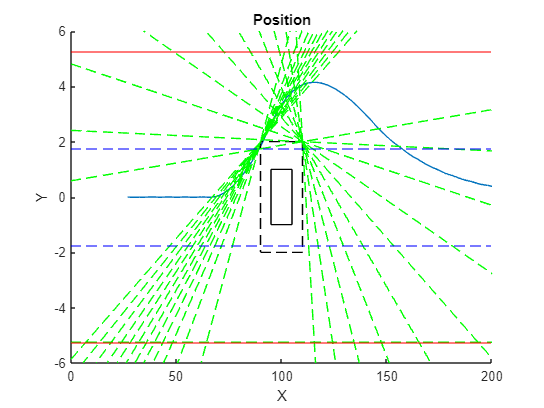

figure
hold on
plot(states(1,:),states(2,:))
%
% % Define obstacle vertices
% obstacle_vertices = [obstacle.fl; obstacle.fr; obstacle.rr; obstacle.rl];
%
% % Plot obstacle
% rectangle('Faces', [1 2 3 4], 'Vertices', obstacle_vertices, 'FaceColor', 'red')
rectangle(Position=[obstacle.rrX,obstacle.rrY,obstacle.Length,obstacle.Width])
rectangle('Position',[obstacle.rrSafeX,obstacle.rrSafeY,obstacle.Length+2*obstacle.safeDistanceX,obstacle.Width+2*obstacle.safeDistanceY],'LineStyle','--')
yline(lanewidth/2,'b--')
yline(-lanewidth/2,'b--')
yline(-lanewidth*lanes/2,'r')
yline(lanewidth*lanes/2,'r')
% xlim([0 500])
ylabel('Y')
xlabel('X')
title('Position')
for i=1:length(slopes)
    X=[0;50;200];
    Y=slopes(i)*X+intercepts(i);
    line(X,Y,'LineStyle','--','Color','g')
end
ylim([-6 6])
xlim([0 200])
hold off

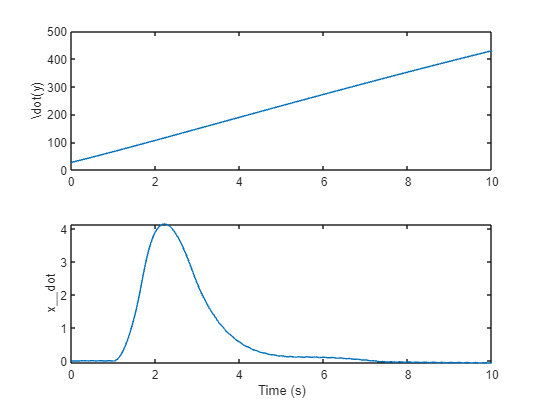

figure
subplot(2,1,1)
plot(T,states(1,:))
ylabel('\dot(y)')
subplot(2,1,2)
plot(T,states(2,:))
ylabel('x__dot')
xlabel('Time (s)')

Plot input

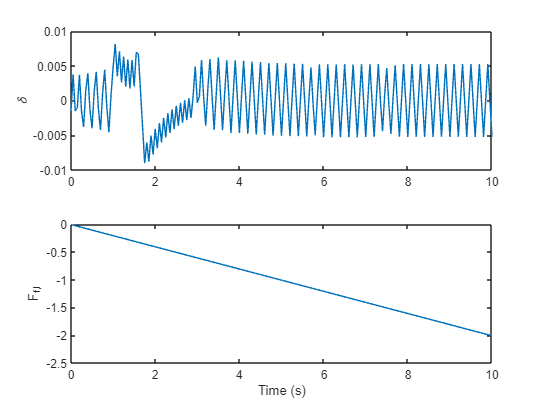

figure
subplot(2,1,1)
plot(T,inputs(1,:))
ylabel('\delta')
subplot(2,1,2)
plot(T,inputs(2,:))
ylabel('F_{f,l}')
xlabel('Time (s)')

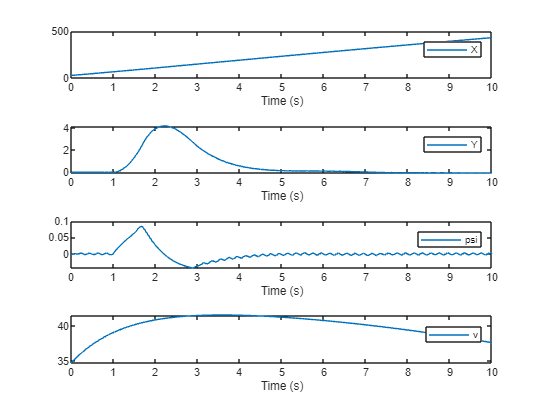



figure
tiledlayout(4,1);
nexttile
plot(T,states(1,:))
legend('X')
xlabel('Time (s)')
nexttile
plot(T,states(2,:))
legend('Y')
xlabel('Time (s)')
nexttile
plot(T,states(3,:))
legend('psi')
xlabel('Time (s)')
nexttile
plot(T,states(4,:))
legend('v')
xlabel('Time (s)')

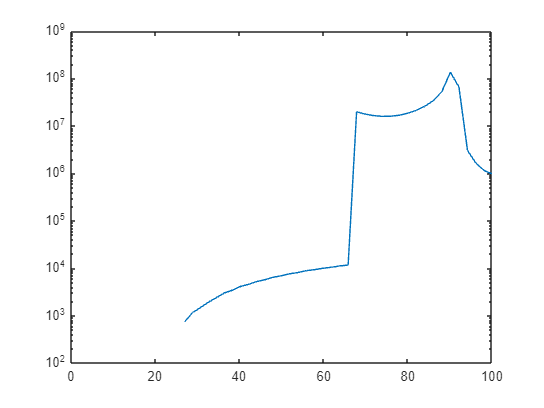

figure
semilogy(states(1,:),costs)
% ylim([0 100])
xlim([0 100])